clc, clear all

## Data of IM

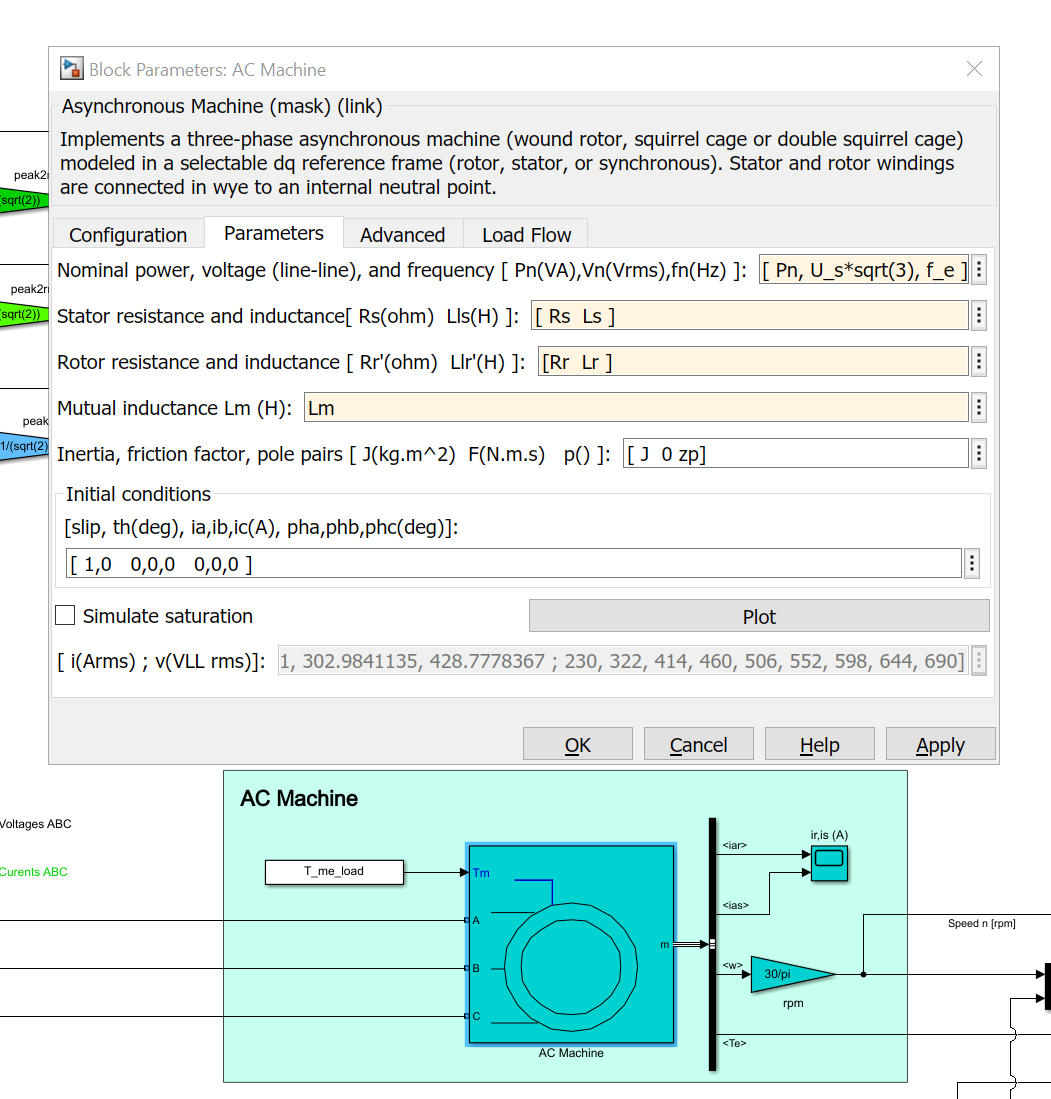x

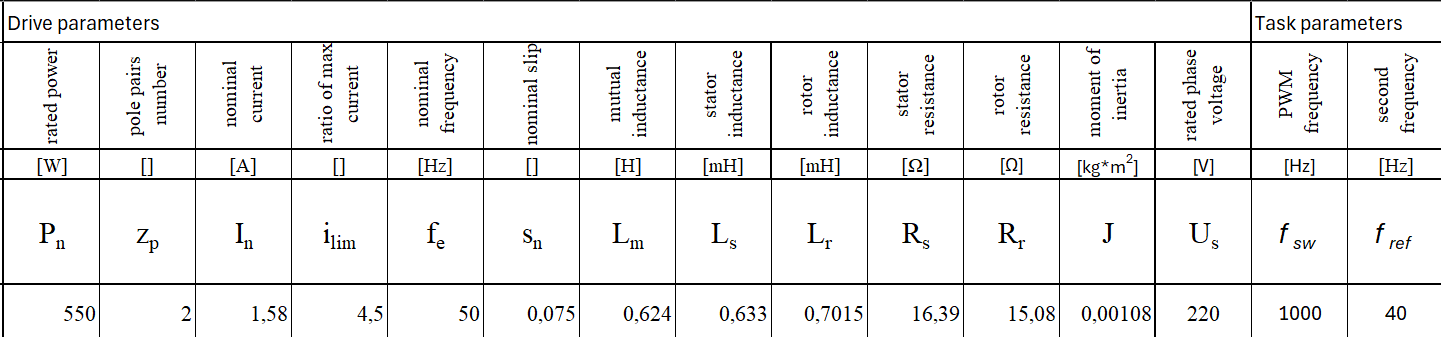

Pn          =       550;%1500                   % - rated power, [W]
zp          =       4;%1                      % - pairs of poles
f_e         =       100;%50;                    % - nominal (rated) frequency, [Hz]
s_n         =       0.075;%0.036                  % - nominal slip
I_n         =       1.58;%2.66;                  % - nominal (rated)current, [А]
i_lim       =       3.5;%4.5;                   % - ratio of max current
Lm          =       0.624;%447e-3                 % - mutual inductance, [H]
Ls          =       633e-6;%484e-6                 % - stator inductance, [H]
Lr          =       701.5e-6;%476e-6                 % - rotor inductance, [H]
Rs          =       16.39;%9.53e-0                % - stator resistance,  [Оhm]
Rr          =       15.08;%5.304e-0               % - rotor resistance,  [Оhm
J           =       0.00108;%0.0025                 % - moment of inertia , [kg*m2]
km          =       i_lim

km = 3.5000

$T_{e_{\textrm{rated}} } =\frac{P_n *z_p }{2*\pi *f_e *\left(1-s_n \right)}*60$ [N*m]

T_e_rated  =      Pn*zp/((1-s_n)*2*pi*f_e) % - nominal (rated) torque, [N*m]

T_e_rated = 3.7853

$\omega_{\textrm{rated}} =2*\pi *f_e *\frac{\left(1-s_n \right)}{z_p }$ [rad/s]w_rated     =       2*pi*f_e*(1-s_n)/zp   % - rated speed [rad/s]

w_rated  =        2*pi*f_e*((1-s_n)/zp)

w_rated = 145.2987

$\omega_{\textrm{idle}} =\frac{2*\pi *f_e }{z_p }$ [rad/s]

w_idle      =       2*pi*f_e/zp;            % - idle speed [rad/s]    

## PWM simulation parameters

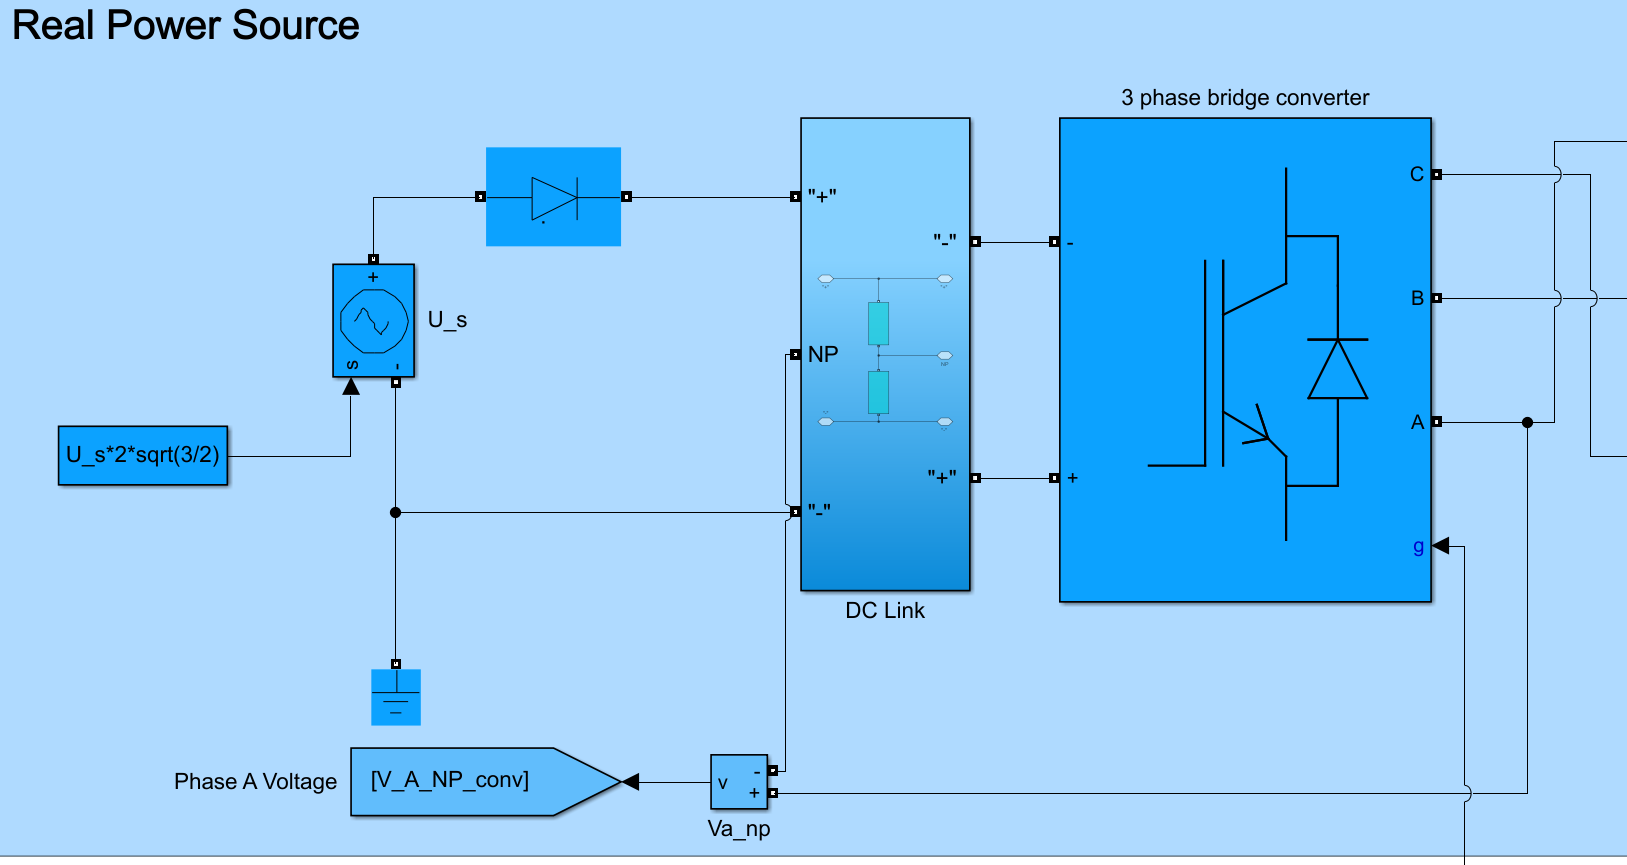

$n_{\textrm{rated}} =\frac{\omega_{\textrm{rated}} }{2*\pi }*60$ [rpm]

n_rated    =        w_rated/2/pi*60        % - rated speed [rpm]

n_rated = 1.3875e+03

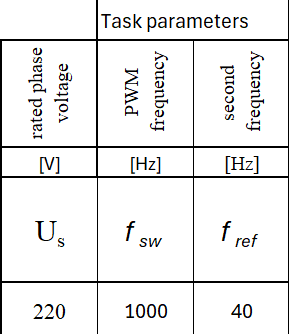

U_s         =      220;                     % - phase (rated) voltage, V 
f_sw        =      2400;%4000;                   % - PWM frequency, Hz   
f_ref       =     50;%25              % - second required speed stator current frequency , [Hz]

$n_{\textrm{ref}} =60*f_{\textrm{ref}} *\frac{\left(1-s_n \right)}{z_p }$ [rpm]

n_ref       =      f_ref/zp*60*(1-s_n)        % - second required speed stator current frequency , [Hz]

n_ref = 693.7500

### Frequency modulation index


$$m_f =\frac{f_{\textrm{sw}} }{f_e }$$


m_f         =       f_sw/f_e                 % - Frequency modulation index at rated speed

m_f = 24

### Switching frequency

f_sw        =       f_e*m_f

f_sw = 2400

w_ref       =       1                        % - speed reference (p.u.)

w_ref = 1

## Uncomment lines 26-28 to simulate second required speed

### Speed reference

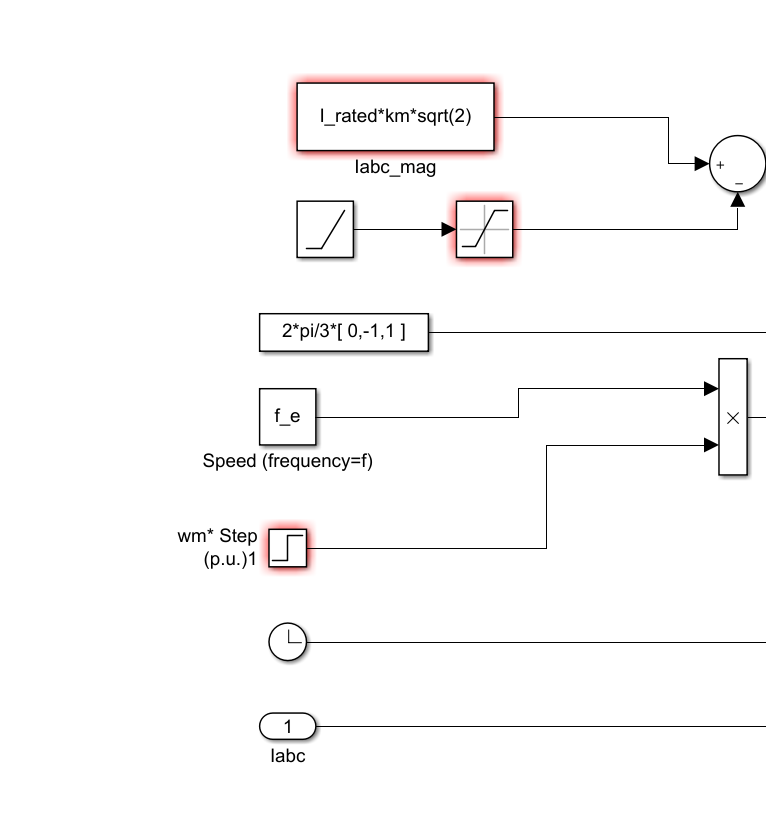    

m_f         =       f_sw/f_ref               % - Frequency modulation index at second required speed

m_f = 48

f_e         =       f_ref

f_e = 50

w_ref       =       n_ref/n_rated            % - voltage reference (p.u.) - this setting automatically do Us/f_e=const

w_ref = 0.5000

### Load torque

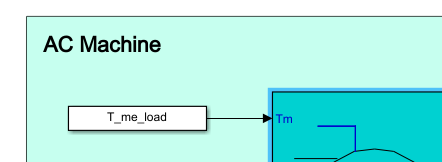

T_me_load   =       1.0*T_e_rated            % - Load torque, [N*m]

T_me_load = 3.7853